clear; clc; close all;
%% Sistema
%P = 5.5;          % cv
P = 5500;      % W
%P = 2 * 396e3   % lbf in / s
w = 1750;   % rpm - Entrada

%Material
E = 190e9;       % Pa - Módulo de elasticidade (SAE 1045)
v = 0.3;         % Coeficiente de Poisson
G = E/(2*(1+v)); % Modulo de rigidez
Sigma_esc = 580; % MPa
Sigma_frat = 690; % MPa

%Localizaçao das forças e reações
a = 15.0;         % mm - Reaçao do primeiro mancal
g = 52.17;        % mm - Força sobre a engrenagem
b = 165.0;        % mm - Reaçao do segundo mancal
p = 246.5;        % mm - Força sobre a polia

%Seçao Transversal
dA  = 60;      %mm - Primeiro mancal
dAB = 80;      %mm - Encosto
dBC = 60;      %mm - Segundo mancal
dC  = 55;      %mm - Polia

%Raios de arredondamento
r_arred = 0.1; %mm

%Geometria
lA  = 25;  %mm - Comprimento A
lAB = 130; %mm - Comprimento B
lBC = 35;  %mm - Comprimento C
lC  = 110; %mm - Comprimento D

lG0 = 35;  %mm - Comprimento até o inicio da chaveta da engrenagem
lG1 = 80;  %mm - Comprimento até o fim da chaveta da engrenagem

lP0 = 193; %mm - Comprimento até o inicio da chaveta da polia
lP1 = 303; %mm - Comprimento até o fim da chaveta da polia

dx = 0.1;
L = lA + lAB + lBC + lC;
z = 0:dx:L;    % mm
D = 60 + (dAB - dA) .* (z>=lA) + (dBC - dAB) .* (z>=(lAB + lA)) + (dC - dBC) .* (z>=(lBC + lAB + lA));
J = (pi/32) .* D .^ 4;    % mm^4
I = (pi/64) .* D .^4;     % mm^4

%Iz = E*(IAB .* (z>=0) .* z.^0 + (IBC-IAB) .* (z>=a) .* (z-a).^0 + (ICD-IBC) .* (z>=b) .* (z-b).^0 + + (ID-ICD) .* (z>=c) .* (z-c).^0);

%Engrenagem
dp = 180;     % mm
phi = 20;  % deg - Angulo de pressao da engrenagem

%Polia
K = 5;      % Relacao entre F1 e F2
dpol = 180; % mm
rpol = dpol / 2000; % m
dy = 0;     % mm - distancia em y dos centros das polias
dx = 100;   % mm - distancia em x dos centros das polias


## Calculo de forças e reações

%Engrenagem
T = 60 * P / (w * 2 * pi)

T = 30.0121

Ftg = 2 * T / dp * 1000;
Frg = Ftg * tand(phi);
Fgx = Frg;
Fgy = Ftg;

%Polia
Fp1 = T / ((K - 1) * rpol)

Fp1 = 83.3669

Fp2 = K * Fp1

Fp2 = 416.8344

Fpy = 0;
Fpx = Fp1 + Fp2;     % N - Rever calculo
%F1 = 132.31F1

%Mancais
R2x = (Fgx * (g - a) + Fpx * (p - a)) / (b - a);
R2y = (Fgy * (g - a) + Fpy * (p - a)) / (b - a);
R1x = Fgx + Fpx - R2x;
R1y = Fgy + Fpy - R2y;

SumX = -R1x + Fgx + Fpx - R2x

SumX = 0

SumY = R1y - Fgy + R2y

SumY = -1.4211e-14

## Diagramas de momento e esforço cortante

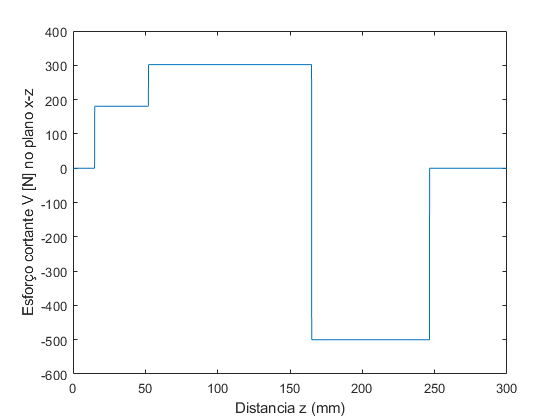


Vx = -R1x .* (z>=a).*(z-a).^0 + Fgx .* (z>=g) .*(z-g).^0 - R2x .* (z>=b) .*(z-b).^0 + Fpx .* (z>=p) .*(z-p).^0;
Mx = -R1x.*(z>=a).*(z-a).^1 + Fgx.*(z>=g).*(z-g).^1 - R2x.*(z>=b).*(z-b).^1 + Fpx.*(z>=p).*(z-p).^1;

figure
plot(z,Vx)
xlabel('Distancia z (mm)')
ylabel('Esforço cortante V [N] no plano x-z')

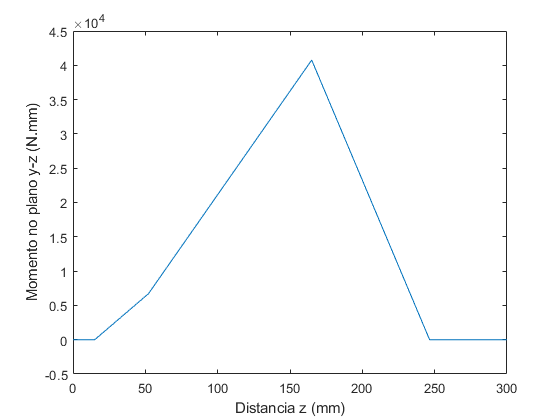


figure
plot(z,Mx)
xlabel('Distancia z (mm)')
ylabel('Momento no plano y-z (N.mm)')

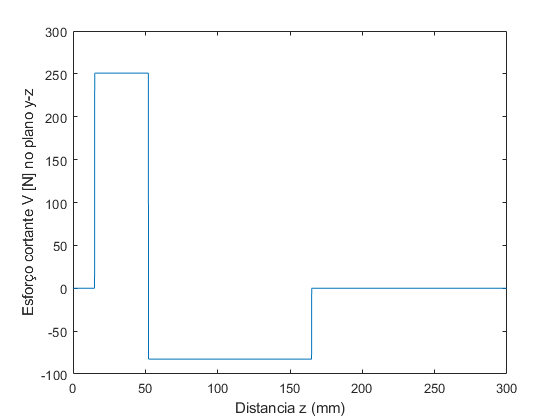


Vy = R1y .* (z>=a).*(z-a).^0 - Fgy .* (z>=g) .*(z-g).^0 + R2y .* (z>=b) .*(z-b).^0 + Fpy .* (z>=p) .*(z-p).^0;
My = R1y.*(z>=a).*(z-a).^1 - Fgy.*(z>=g).*(z-g).^1 + R2y.*(z>=b).*(z-b).^1 + Fpy.*(z>=p).*(z-p).^1;

figure
plot(z,Vy)
xlabel('Distancia z (mm)')
ylabel('Esforço cortante V [N] no plano y-z')

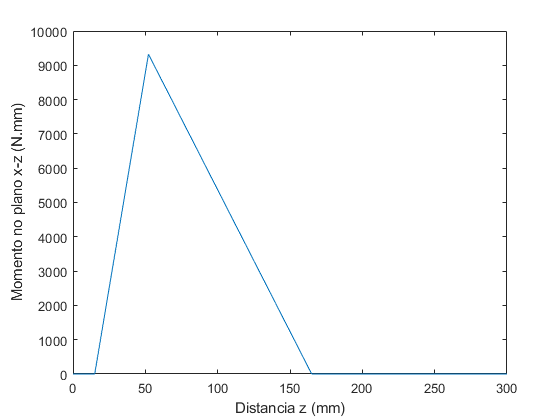


figure
plot(z,My)
xlabel('Distancia z (mm)')
ylabel('Momento no plano x-z (N.mm)')

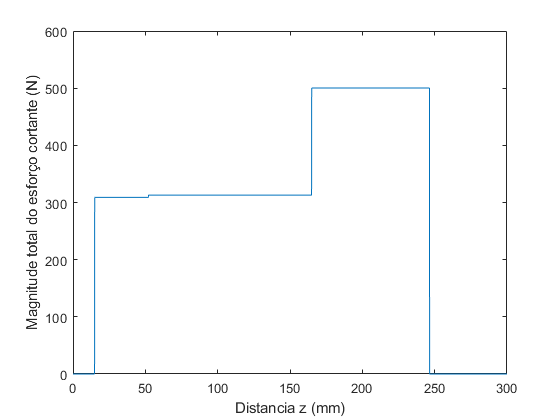


V = (Vx.^2 + Vy.^2).^(1/2);
figure
plot(z,V)
xlabel('Distancia z (mm)')
ylabel('Magnitude total do esforço cortante (N)')

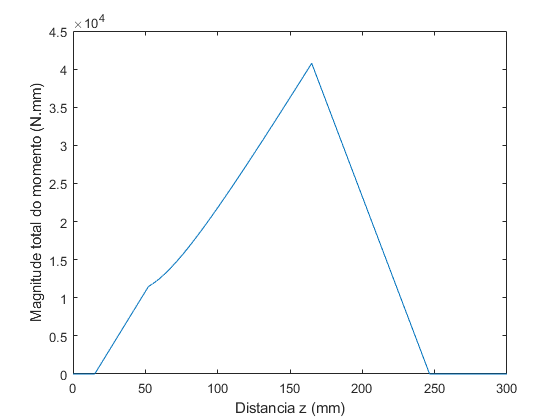


figure
M = (Mx.^2 + My.^2).^(1/2);
plot(z,M)
xlabel('Distancia z (mm)')
ylabel('Magnitude total do momento (N.mm)')

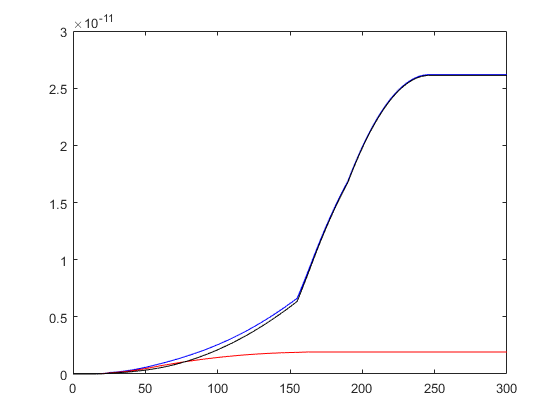


indexAB = int8(lA/dx)+2;
indexBC = int8(lAB/dx)+2;
indexC = int8(lBC/dx)+2;

JA  = J(1);
JAB = J(indexAB);
JBC = J(indexBC);
JC  = J(indexC);

THETA = (T/G)*(lA/JA + lAB/JAB + lBC/JBC + lC/JC); % rad
THETAdeg = THETA * (360/(2*pi)); % deg

Iz = E .* I;
%Iz = E*(IAB .* (z>=0) .* z.^0 + (IBC-IAB) .* (z>=a) .* (z-a).^0 + (ICD-IBC) .* (z>=b) .* (z-b).^0 + + (ID-ICD) .* (z>=c) .* (z-c).^0);


%figure
%plot(z,Iz)
%xlabel('Distance along the z axis (in)')
%ylabel('Moment in x-z plane (lbf in)')


%% Solução Numérica
M_Ei_x = Mx./Iz;
M_Ei_y = My./Iz;

def_ang_x = modTrapInt(z,M_Ei_x);
def_x = modTrapInt(z,def_ang_x);

def_ang_y = modTrapInt(z,M_Ei_y);
def_y = modTrapInt(z,def_ang_y);

def_ang = (def_ang_x.^2+def_ang_y.^2).^(1/2);


%% plot
figure
plot(z, def_ang,'b');hold on
plot(z, def_ang_y, 'r');
plot(z, def_ang_x,'k');

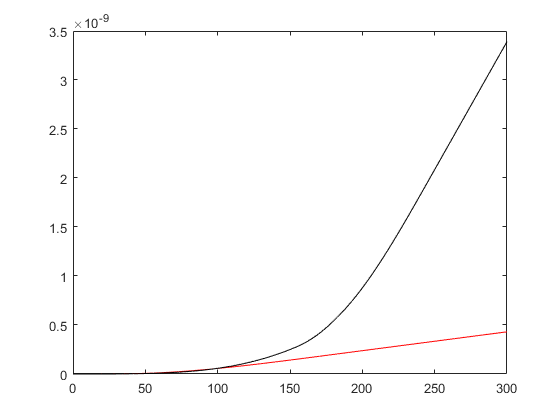


figure
plot(z, def_y, 'r');hold on
plot(z, def_x,'k');

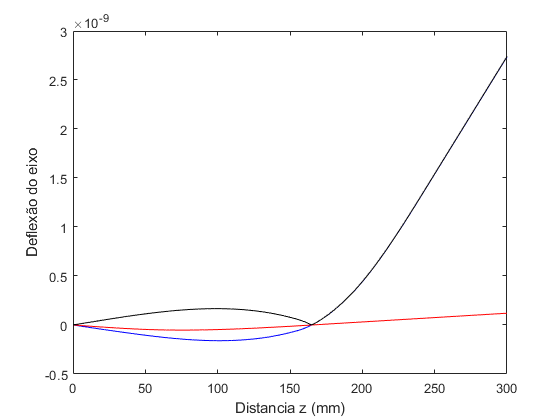


% Correção
C3x = atan(def_x(z==b)/b);
C3y = atan(def_y(z==b)/b);

def_tot_cor_x = def_x-C3x.*z;
def_tot_cor_y = def_y-C3y.*z;
def_tot_cor = (def_tot_cor_x.^2+def_tot_cor_y.^2).^(1/2);

def_ang_cor_x = def_ang_x-C3x;
def_ang_cor_y = def_ang_y-C3y;
def_ang_cor = (def_ang_cor_x.^2+def_ang_cor_y.^2).^(1/2);

figure
plot(z, def_tot_cor_x, 'b'); hold on
plot(z, def_tot_cor_y, 'r'); hold on
plot(z, def_tot_cor, 'k'); 
xlabel('Distancia z (mm)')
ylabel('Deflexão do eixo')


figure
plot(z, def_ang_cor_x, 'b'); hold on
plot(z, def_ang_cor_y, 'r'); hold on
plot(z, def_ang_cor, 'k'); hold on
xlabel('Distancia z (mm)');
ylabel('Torção do eixo');

%%Calculo de tensoes

% Tensao normal de flexao
sigma_x = Mx .* (D/2) ./ I;
sigma_y = My .* (D/2) ./ I;
sigma = M .* (D/2) ./ I;

% Cisalhamento devido ao torque
tau_xy = T .* (D/2) ./ J;

%%Concentradores de tensao
Neuber_a = 0.062 * (25.4 ^ 0.5);    % mm^1/2 - Flexao
Neuber_as = 0.049 * (25.4 ^ 0.5);   % mm^1/2 - Torçao

q  = 1 ./ (1 + Neuber_a  ./ ((D/2) .^ 0.5));
qs = 1 ./ (1 + Neuber_as ./ ((D/2) .^ 0.5));

%Engrenagem - chaveta
Ktg = 2.45;
Ktsg = 3.25;

%Polia - chaveta
Ktp = 2.2;
Ktsp = 3;

% REVER SEÇAO AO MUDAR GEOMETRIA (ratio)
%Escalonamento A
ratio = dAB/dA

ratio = 1.3333

Kta = (0.97098 + (ratio - 1.2) * (0.93836 - 0.97098) / 0.3) * (r_arred / dA) ^ (-0.21796 + (ratio - 1.2) * (-0.25759 + 0.21796) / 0.3);
Ktsa = 0.84897 * (r_arred / dA) ^ (-0.23161);

%Escalonamento B
ratio = dAB/dBC

ratio = 1.3333

Ktb = (0.97098 + (ratio - 1.2) * (0.93836 - 0.97098) / 0.3) * (r_arred / dBC) ^ (-0.21796 + (ratio - 1.2) * (-0.25759 + 0.21796) / 0.3);
Ktsb = 0.84897 * (r_arred / dBC) ^ (-0.23161);

%Escalonamento C
ratio = dBC/dC

ratio = 1.0909

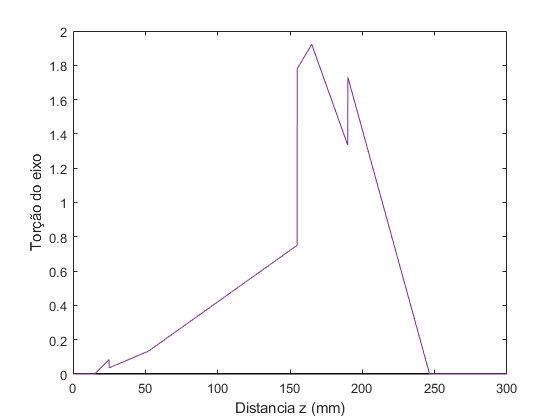

Ktc = 0.90337 * (r_arred / dC) ^ (-0.12692);
Ktsc = (0.97527 + (ratio - 1.07) * (0.95120 - 0.97527) / 0.03) * (r_arred / dBC) ^ (-0.20958 + (ratio - 1.07) * (-0.23757 + 0.20958) / 0.03);

Kt = Kta .* (z>=lA) - Kta .* (z>=lA + dx) + Ktg .* (z>=lG0) - Ktg .* (z>=lG1) ...
    + Ktb .* (z>=lA+lAB) - Ktb .* (z>=lA+lAB+dx) + Ktc .* (z>=lA+lAB+lBC) - Ktc .* (z>=lA+lAB+lBC+dx) ...
    + Ktp .* (z>=lP0) - Ktp .* (z>=lP1);

Kts = Ktsa .* (z>=lA) - Ktsa .* (z>=lA + dx) + Ktsg .* (z>=lG0) - Ktsg .* (z>=lG1) ...
    + Ktsb .* (z>=lA+lAB) - Ktsb .* (z>=lA+lAB+dx) + Ktsc .* (z>=lA+lAB+lBC) - Ktsc .* (z>=lA+lAB+lBC+dx) ...
    + Ktsp .* (z>=lP0) - Ktsp .* (z>=lP1);

Kf = 1 + q .* (Kt - 1);
Kfs = 1 + qs .* (Kts - 1);

%Aplicando os concentradores
plot(z,sigma_x)

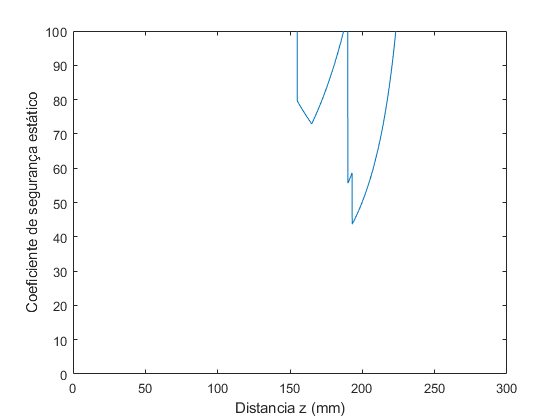

sigma_x = sigma_x .* Kf;
sigma_y = sigma_y .* Kf;
sigma = sigma .* Kf;
tau_xy = tau_xy .* Kfs;

%Criterio de falha estatico
tensao_eq = (( (sigma_x - sigma_y) .^ 2 + sigma_x .^ 2 + sigma_y .^ 2 + 6 * tau_xy .^ 2) /2) .^ 0.5;
N_est = Sigma_esc ./ tensao_eq;
figure
plot(z, N_est)
xlim([0,300])
ylim([0,100])
xlabel('Distancia z (mm)');
ylabel('Coeficiente de segurança estático');


%Tensao de fadiga
tensao_alt = sigma;
tensao_med = tau_xy * (3 ^ 0.5);
Cs = 1.189 * D .^ (-0.097);
Ce = 1;
Cf = min(1,4.51 * Sigma_frat ^ (-0.265))

Cf = 0.7978

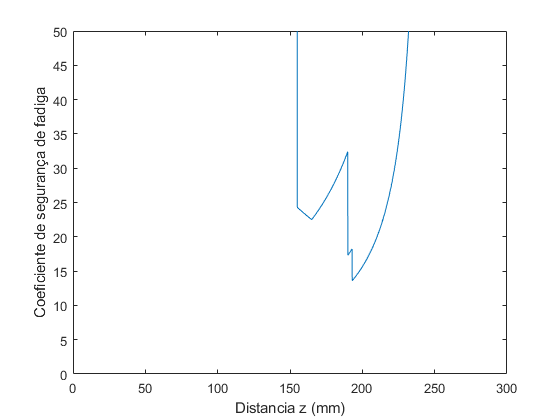

Ct = 1;
Cr = 0.814;
tensao_fad = 0.5 * Sigma_frat * Cs * Ce * Cf * Ct * Cr;
%Linha de carga 3
N_fad = tensao_fad * Sigma_frat ./ (tensao_alt * Sigma_frat + tensao_med .* tensao_fad);
figure
plot(z, N_fad)
xlim([0,300])
ylim([0,50])
xlabel('Distancia z (mm)');
ylabel('Coeficiente de segurança de fadiga');

min(N_fad)

ans = 13.5946